# Logistic Growth

Created By: Samuel Bechara, PhD

Created on: 20 April 2021

## Exponential Growth

This is the most simple model that takes the form:


$$\frac{\textrm{dN}}{\textrm{dt}}=\textrm{rN}$$


- N is the number of individuals in the population

- r is the Mathusian growth rate. This accounts for births AND deaths. r = b - d

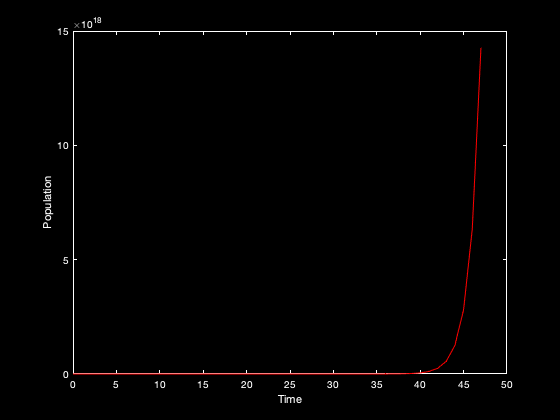

clear;clc;close all;

% The time period over which you wish to analyze dynamics
t_length = 47;

t = 0:t_length;
N = zeros(1,length(t));

% How many bacteria you start with
N(1) = 400;

% Growth Rate - a rate r=2 implies the bacteria double every time period
r =1.25;

for i = 1:length(t)-1
    N(i+1)=N(i)+r*N(i);
end

% Plotting stuff. Students like black background
plot(t,N,'-','LineWidth',.1,'MarkerSize',1.2,'Color',[1 0 0])
set(gca,'color','k','xcolor','w','ycolor','w')
set(gcf,'color','k')
xlabel('Time')
ylabel('Population')
title('Exponential Growth')

## Logistic Growth

This is a more realistic model in that we are accounting for limitations of the environment.


$$\frac{\textrm{dN}}{\textrm{dt}}=\textrm{rN}\left(1-\frac{N}{K}\right)$$


The equation above is the "logistic equation". 

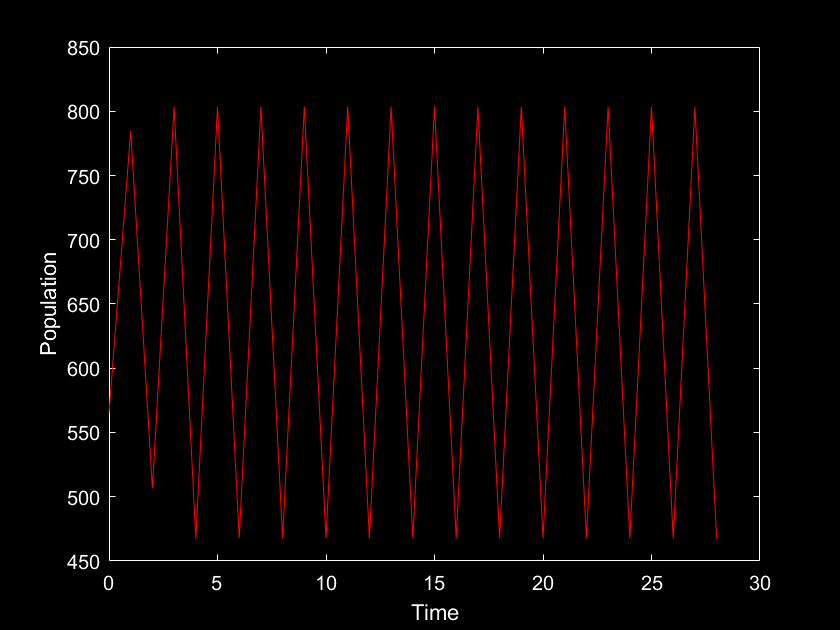

clear;clc;close all;

% The time period over which you wish to analyze dynamics
t_length = 28;

t = 0:t_length;
N = zeros(1,length(t));

% How many individuals you start with
N(1) = 565;


% Growth Rate
r =2.3;

% The carrying capacity of the environment
k = 680;


for i = 1:length(t)-1    
    N(i+1) = N(i)+r*N(i)*(1-(N(i)/k));
    if N(i+1) <= 0 % means the population has died
        N(i+1:end) = 0;
        break
    end
end

plot(t,N,'-','LineWidth',.1,'MarkerSize',1.2,'Color',[1 0 0])
set(gca,'color','k','xcolor','w','ycolor','w') % gca for axes
set(gcf,'color','k') % gcf for figure
xlabel('Time')
ylabel('Population')

## The Logistic Map

The logistic map, or logisitic difference equation is shown below.


$$N_{t+1} =\beta N_i \left(1-\frac{N_i }{K}\right)$$


In this case:

- $\beta$ is a dimensionless population growth factor. If it is less than one, that indicates that more individuals are dying each generation than being born. Etc.

- $N_i$ is the population of the ith generation

Even though it *looks* similar to logistic growth, the dynamics are significantly different.

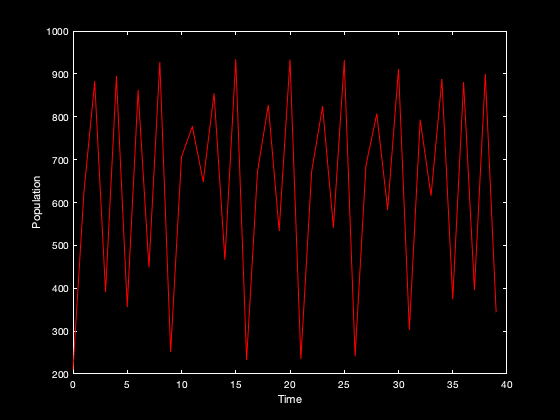

clear;clc;close all;

% The time period over which you wish to analyze dynamics
t_length = 39;

t = 0:t_length;
N = zeros(1,length(t));

% How many individuals you start with
N(1) = 210;

% The dimensionless growth factor
beta =3.75;

% The carrying capacity of the environment
k = 1000;


for i = 1:length(t)-1    
    N(i+1) = beta*N(i)*(1-(N(i)/k));
    if N(i+1) <= 0 % means the population has died
        N(i+1:end) = 0;
        break
    end
end

plot(t,N,'-','LineWidth',.1,'MarkerSize',1.2,'Color',[1 0 0])
set(gca,'color','k','xcolor','w','ycolor','w') % gca for axes
set(gcf,'color','k') % gcf for figure
xlabel('Time')
ylabel('Population')

## Lets try and explain the "steady state" behavior that we are seeing (Logistic Map)

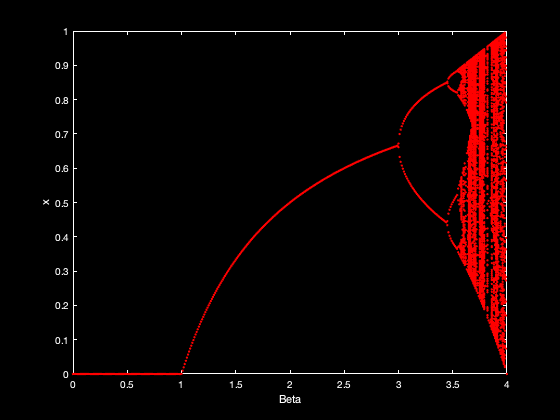

clear;clc;close all;

Nvals = [];

for beta = 0:.01:4
    beta;
    Nold = 0.5;
    % transient (not going to save)
    % essentially we are trying to see what "steady state" is
    for i = 1:2000
        Nnew = ((Nold-Nold^2)*beta); % k = 1, arbitrary k
        Nold = Nnew;
    end
    Nss = Nnew; % x steady state
    for i = 1:1000
        Nnew = ((Nold-Nold^2)*beta);
        Nold = Nnew;
        Nvals(1,length(Nvals)+1) = beta;
        Nvals(2,length(Nvals)) = Nnew;
        if(abs(Nnew-Nss)<0.001)
            break
        end
    end
end

plot(Nvals(1,:),Nvals(2,:),'.','LineWidth',.1,'MarkerSize',1.2,'Color',[1 0 0]);
set(gca,'color','k','xcolor','w','ycolor','w')
set(gcf,'color','k')
xlabel('Beta')
ylabel('x')


% As we increase Beta between 0 and 1 it goes to 0
% Beta from 1-3 is a single fixed point
% at Beta 3 we get 2 solutions, (periodic orbit)

## Don't remove the transient, what will it look like?

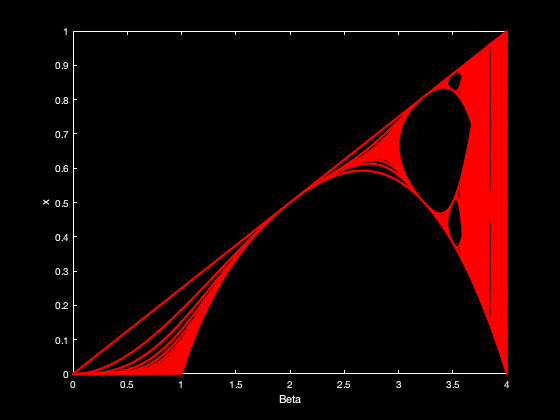

clear;clc;close all;

Nvals = [];

for beta = 0:.001:4
    beta;
    Nold = 0.5;
%     % transient (not going to save)
%     for i = 1:2000
%         xnew = ((xold-xold^2)*beta);
%         xold = xnew;
%     end
Nnew = Nold;
    Nss = Nnew; % x steady state
    for i = 1:10000
        Nnew = ((Nold-Nold^2)*beta);
        Nold = Nnew;
        Nvals(1,length(Nvals)+1) = beta;
        Nvals(2,length(Nvals)) = Nnew;
        if(abs(Nnew-Nss)<0.001)
            break
        end
    end
end

plot(Nvals(1,:),Nvals(2,:),'.','LineWidth',.1,'MarkerSize',1.2,'Color',[1 0 0]);
set(gca,'color','k','xcolor','w','ycolor','w')
set(gcf,'color','k')
xlabel('Beta')
ylabel('x')

## Lets "enhance"

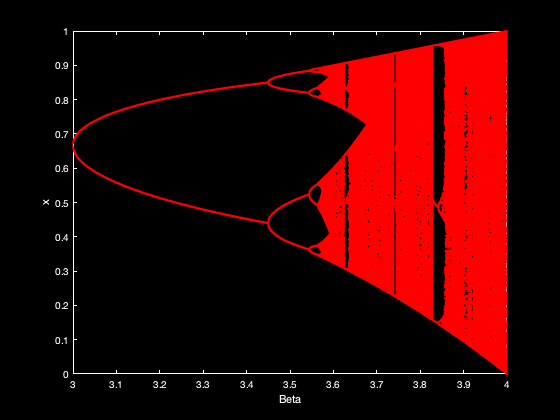

clear;clc;close all;

Nvals = [];

for beta = 0:.001:4
    beta;
    Nold = 0.5;
    % transient (not going to save)
    for i = 1:2000
        Nnew = ((Nold-Nold^2)*beta);
        Nold = Nnew;
    end
    Nss = Nnew; % x steady state
    for i = 1:10000
        Nnew = ((Nold-Nold^2)*beta);
        Nold = Nnew;
        Nvals(1,length(Nvals)+1) = beta;
        Nvals(2,length(Nvals)) = Nnew;
        if(abs(Nnew-Nss)<0.001)
            break
        end
    end
end

plot(Nvals(1,:),Nvals(2,:),'.','LineWidth',.1,'MarkerSize',1.2,'Color',[1 0 0]);
set(gca,'color','k','xcolor','w','ycolor','w')
set(gcf,'color','k')
xlabel('Beta')
ylabel('x')
xlim([3 4])